# Autocorrelation

clear
load("Data/MATLAB_data/Experimental_data_0.mat")
plot(time, data,'.')
M = mean(data)

M = 0.5337

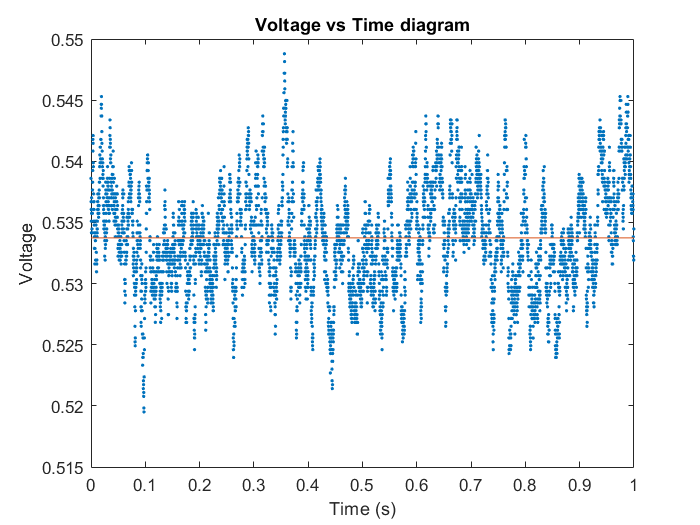

hold on
plot(time, zeros(1, 5000) + M)
hold off
xlabel('Time (s)')
ylabel('Voltage')
title('Voltage vs Time diagram')

s_k = zeros(5000,1);
for k = 0:4999
    i = 5000 - k;
    t1 = data(1:i) - M;
    t2 = data(1+k:i+k) - M;
    s_k(k+1) = sum(t1 .* t2);    
end
var = sum((data - M).^2);
B_xx = s_k ./ var;
plot(time, B_xx, '.')
hold on 
%These are datapoints so we graph using points
sum = 0;
j = 1;
while B_xx(j)*B_xx(j+1) > 0
    traps = B_xx(j) + B_xx(j+1);
    dt = time(j+1) - time(j);
    sum = sum + dt*traps/2;
    j = j+1;
end
time(j);
T = trapz(time(1:j),B_xx(1:j))

T = 0.0059

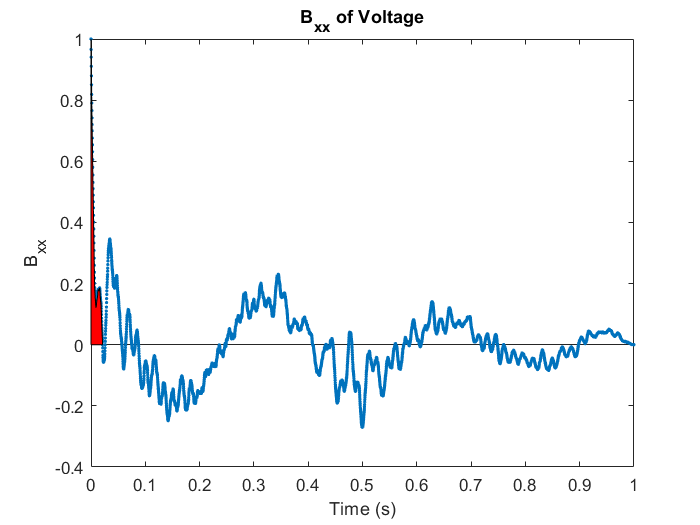

sum;
H1=area(time(1:j),B_xx(1:j),'FaceColor',[1 0 0]);
hold off
xlabel('Time (s)')
ylabel('B_{xx}')
title('B_{xx} of Voltage')

sigma = sqrt(var/10000)

sigma = 0.0029

N = 1/(2 * T)

N = 85.1614